# Generating PDM Wavetable Samples

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

## **1   PDM Characteristic Curve**

fprintf(['_____________________________________________________________________\n' ...
  '1 PDM Characteristic Curve']);

_____________________________________________________________________
1 PDM Characteristic Curve

### 1.1   Piecewise Linear Function

fprintf('1.1 Piecewise Linear Function\n');

1.1 Piecewise Linear Function


As explained in Section "Phase Distortion Modulation" in the report, the phase distortion characteristic curve consists of two straigt sections

    $f_1(\varphi)=a\varphi$,        $0\leq\varphi\leq\varphi_B$,    running through the points $(0,0)$ and $(\varphi_B,\pi)$ and

    $f_2(\varphi) = b\varphi+c$,  $\varphi_B\leq \varphi< 2\pi$,  running through the points $(\varphi_B,\pi)$ and $(2\pi,2\pi)$.

Here, $\varphi_B$ denotes the phase angle of the bend, i.e., the intersection of the two straight sections. I will refer to $(\varphi_b,\pi)$ as the "bend" point. Taking the slope $a$ of the first section as a variable parameter with $a\geq 1$, we can compute $\varphi_B$, $b$, and $c$.

syms a b c phi phiB real;
assume(a>=0);
eqns = [           ...
  a*phiB   == pi,  ...
  b*phiB+c == pi,  ...
  b*2*pi+c == 2*pi ...
];
S = solve(eqns,[phiB,b,c]);
phiB = simplify(S.phiB); fprintf('  phiB ='); disp(phiB);

  phiB =

$$\frac{\pi }{a}$$

b    = simplify(S.b);    fprintf('  b ='   ); disp(b);

  b =

$$\frac{a}{2\,a-1}$$

c    = simplify(S.c);    fprintf('  c ='   ); disp(c);

  c =

$$\frac{2\,\pi \,\left(a-1\right)}{2\,a-1}$$

Hence, the phase distortion modulation characteristics curve is

    
$$\varphi_a(\varphi) = \begin{cases}
  a\varphi &\text{for } 0\leq\varphi<\frac{\pi}{a}\\
  \frac{a\varphi+2\pi(a-1)}{2a-1} &\text{for }\frac{\pi}{a}\leq\varphi<2\pi.
\end{cases}$$


This characteristic is implemented by the function `phipd=vVZtools.PDMcc(phi,a)`.

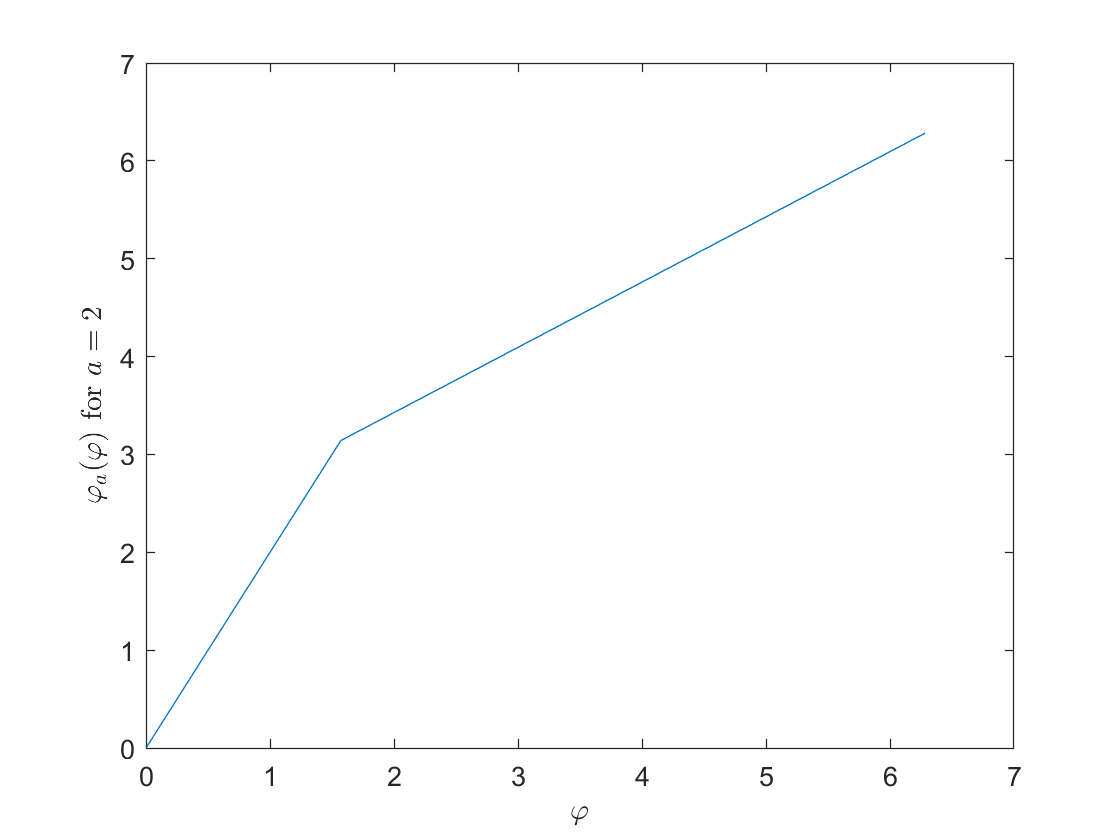

x = 0:0.01*pi:2*pi;
y = vVZtools.PDMcc(x,2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\varphi_a(\varphi)$$ for $$a=2$$','Interpreter','latex');

### 1.2   Modulation Angle Parameter

fprintf('\n1.2 Modulation Angle Parameter');


1.2 Modulation Angle Parameter

The modulation angle parameter $\vartheta$ can be computed from the slope parameter $a$ as follows

    $\vartheta = 180°-\arctan(a)+\arctan(b) = 180°-\arctan(a)+\arctan\left(\frac{a}{2a-1}\right)$.

fprintf('Modulation angle theta as function of slope paramerter a');

Modulation angle theta as function of slope paramerter a

fprintf('- Symbolic solution');

- Symbolic solution

syms theta real;
assume(theta>0 & theta<=pi & a>=1);
eqns = theta==pi-atan(a)+atan(b);
solve(eqns,a);

There seems to be no explicit inverse function (and I do not know it any better). Hence we plot $\vartheta(a)$and compute a lookup table.

fprintf('- Plot');

- Plot

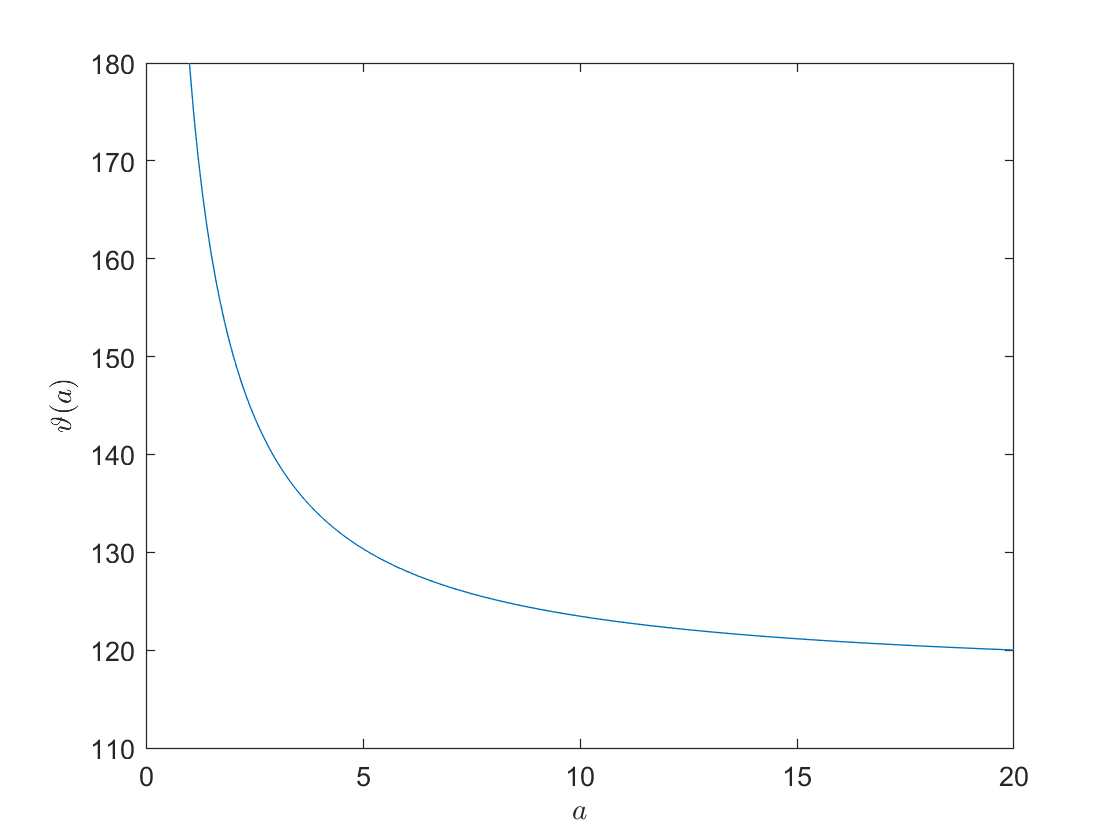

x = 1:0.1:20;
y = vVZtools.pdmA2theta(x);
plot(x,y);
ylim([110 180]);
xlabel('$$a$$','Interpreter','latex');
ylabel('$$\vartheta(a)$$','Interpreter','latex');


fprintf('- Lookup table');

- Lookup table

for i=120:5:180
  theta = i/180*pi;
  S = solve(theta==pi-atan(a)+atan(b),a); 
  fprintf('  phi = %d°\n  -> a = %g =',i,eval(S)); disp(S);
end

  phi = 120°
  -> a = 20.0702 =

$$-\frac{\sqrt{3}+\sqrt{7}+1}{\sqrt{3}-2}$$

  phi = 125°
  -> a = 8.18719 =

$$-\frac{\tan\left(\frac{11\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{11\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{11\,\pi }{36}\right)-2}$$

  phi = 130°
  -> a = 5.13641 =

$$-\frac{\tan\left(\frac{5\,\pi }{18}\right)+\sqrt{2\,{\tan\left(\frac{5\,\pi }{18}\right)}^{2}+1}+1}{\tan\left(\frac{5\,\pi }{18}\right)-2}$$

  phi = 135°
  -> a = 3.73205 =

$$\sqrt{3}+2$$

  phi = 140°
  -> a = 2.92095 =

$$-\frac{\tan\left(\frac{2\,\pi }{9}\right)+\sqrt{2\,{\tan\left(\frac{2\,\pi }{9}\right)}^{2}+1}+1}{\tan\left(\frac{2\,\pi }{9}\right)-2}$$

  phi = 145°
  -> a = 2.3908 =

$$-\frac{\tan\left(\frac{7\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{7\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{7\,\pi }{36}\right)-2}$$

  phi = 150°
  -> a = 2.0162 =

$$-\frac{\sqrt{3}+\sqrt{15}+3}{\sqrt{3}-6}$$

  phi = 155°
  -> a = 1.7371 =

$$-\frac{\tan\left(\frac{5\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{5\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{5\,\pi }{36}\right)-2}$$

  phi = 160°
  -> a = 1.52116 =

$$-\frac{\tan\left(\frac{\pi }{9}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{9}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{9}\right)-2}$$

  phi = 165°
  -> a = 1.34946 =

$$\frac{\sqrt{3}\,\left(\sqrt{15-8\,\sqrt{3}}-\sqrt{3}+3\right)}{3}$$

  phi = 170°
  -> a = 1.21017 =

$$-\frac{\tan\left(\frac{\pi }{18}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{18}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{18}\right)-2}$$

  phi = 175°
  -> a = 1.09548 =

$$-\frac{\tan\left(\frac{\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{36}\right)-2}$$

  phi = 180°
  -> a = 1 =

$$1$$

## 2   VZ Wavetable Samples `SINE` and `SAW1` ... `SAW5`

fprintf(['_____________________________________________________________________\n' ...
  '2 VZ Wavetable Samples SINE and SAW1 ... SAW5']);

_____________________________________________________________________
2 VZ Wavetable Samples SINE and SAW1 ... SAW5

### 2.1   PD-Modulated Cosine Waves

fprintf('2.1 PD-Modulated Cosine Waves');

2.1 PD-Modulated Cosine Waves

VZ-1/VZ-10M seem to use cosine instead of sine carrieres for PDM. Hence we start with one cycle of cosine

    $x(\varphi)
= \cos(\varphi)
= \sin\left(\varphi+\frac{\pi}{2}\right)$   with $0\leq\varphi<2\pi$.

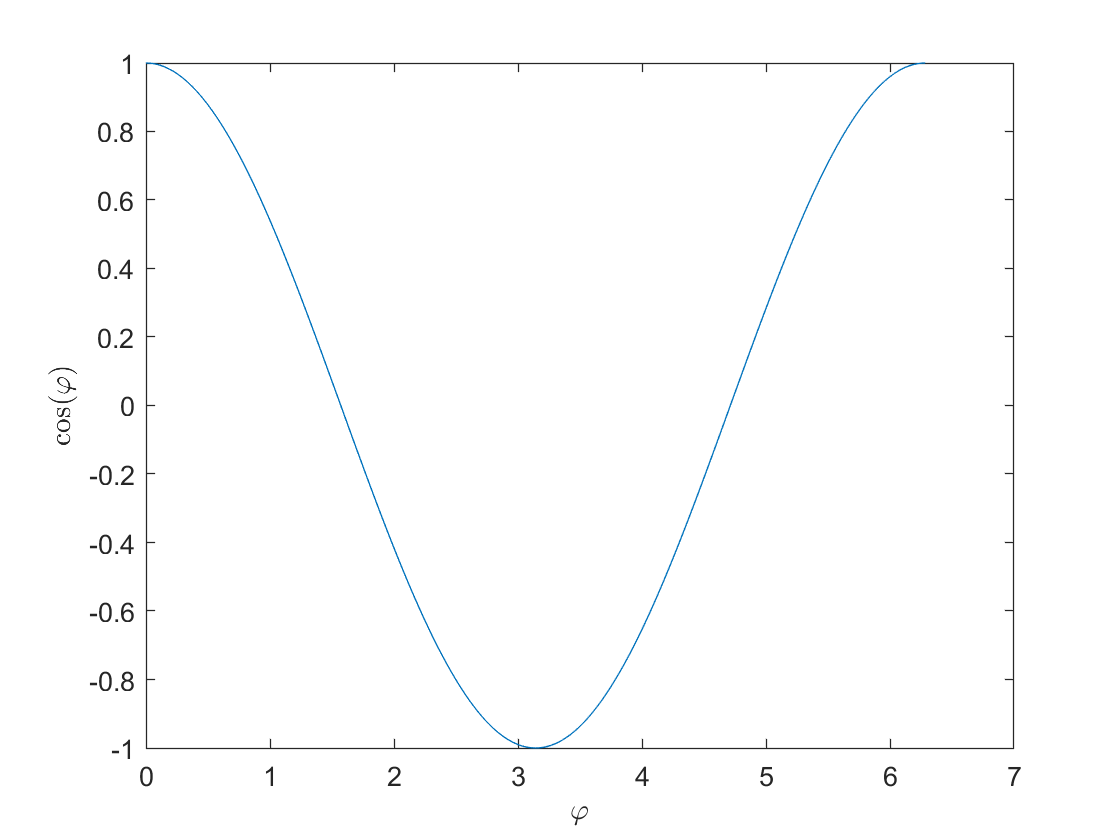

x = 0:0.01*pi:2*pi;
y = cos(x);
figure
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\cos(\varphi)$$','Interpreter','latex');

PD modulation of that cosine wave can be written as

    $y(\varphi) 
= x\big(\varphi_a(\varphi)\big) 
= \cos\big(\varphi_a(\varphi)\big)$.

Example for $a=2$:

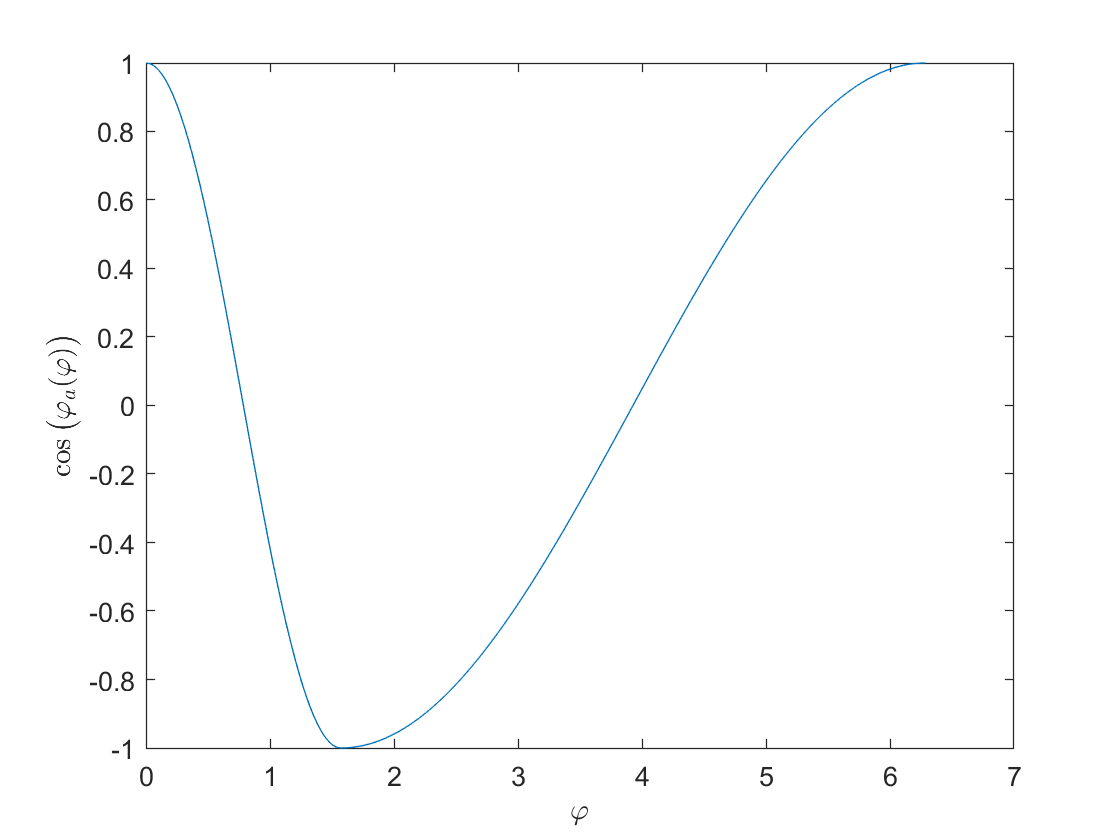

x = 0:0.01*pi:2*pi;
y = cos(vVZtools.PDMcc(x,2));
figure
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\cos\big(\varphi_a(\varphi)\big)$$','Interpreter','latex');

### 2.2   Cutting Recorded Wavetable Samples

fprintf('2.2 Cutting Recorded Wavetable Samples');

2.2 Cutting Recorded Wavetable Samples

For generating the waves, I use a sampling frequency $f_S=48\,\text{kHz}$ and a cycle length of $K=1024$ samples. Thus, the samples have a "natural" frequency of

    
$$f_0 = \frac{f_S}{K} = \frac{48000\,\text{Hz}}{1024} = 46.875\,\text{Hz}$$


which corresponds to the musical note F#1 plus 23 cents.

I recorded the the eight waveforms of VZ-1 from a single oscillator (`M1`) and with the following pitch and waveform settings:

- Menu `3-00`: `TUNE(A4)=440.0` (Hz),

- Menu `1-02`: `PITCH FIX=ON`, `OCT=02`, `NOTE=00`, `FINE=09`, and

- Menu `1-01`: `FORM=`[`SINE`, `SAW1`, `SAW2`, `SAW3`, `SAW4`, `SAW5`, `NOISE1`, `NOISE2`].

I labelled fallign edge zero-crossings in the recordings usind the `annotator.mlapp` tool. The recordings are located in `<vVZ>/waves/recordings/phaseDistortionModulationAnalysis`, the respective pitch mark labels in  `<vVZ>/labels/recordings/phaseDistortionModulationAnalysis`. Using the `vVZtools.cutNiceCycle` function I cut one wave cycle

    $w(k)$ with $0\leq k< K=1024$

for each of the the SINE and SAWn recordings. I found phase shifts between the zero-crossings and the bends in the signal cycles caused by PDM which I compensate by a parameter $k_{0,y}$ (measured in samples):

    
$$y(k)=w\big((k+k_{0,y})\,\text{mod}\,K\big)$$


where$y(k)$ denotes the phase-corrected wave cycle used for PDM reverse-engineering. I save $y(k)$ for the `SINE` and `SAWn` waveforms in `<vVZ>/waves/wavetable/sampled` for later use in the wavetable oscillators of the virtual instrument.

The hypothesized origin of the VZ-1 waveforms `SAW1` ... `SAW5` is piecewise linear phase distortion modulation (PDM) as described above of a cosine carrier signal. Using the phase angle $\varphi=2\pi\,k/K,$ we can rewrite PDM as

    
$$y(k) = \cos\left(2\pi\,K\,f_a\left(2\pi\frac{k}{K}\right)\right)$$


Also the carrier signal seems to be phase-shifted, which I account for by another parameter $k_{0,x2}$, again measured in samples. Hence the model of the carrier signal is

    $x_2(k) = \cos\left(2\pi\frac{k+k_{0,x2}}{K}\right)$.

The PD-model of the oscillator output signal is then

    $y(k)=\sin\left(2\pi\frac{k+Kx_1(k)+k_{0,x2}}{K}+\frac{\pi}{2}\right)$,

where $x_1(k)$ is a phase-modulating signal. Comparing with the phase *distortion* modulation equation above, we see that

    $\varphi_{\text{PD}}(\varphi)=2\pi\frac{k+k_{0,x2}}{K}+2\pi x_1(k)$   or   $x_1(k)=\frac{\varphi_{\text{PD}}(\varphi)}{2\pi} - \frac{k+k_{0,x2}}{K}$.

I numerically solve for $x_1(k)$ and expect the solution to be

- identical to 0 if $y$ is a `SINE` waveform and

- a triangle signal if $y$ if one of the `SAW1` ... `SAW5` waveforms.

SINE


vVZtools.loadRecording(rid="recordings/phaseDistortionModulationAnalysis/SINE")
- Read wave file "../waves/recordings/phaseDistortionModulationAnalysis/SINE.wav"
  - OK, 100260 samples
- Read annotation file "../labels/recordings/phaseDistortionModulationAnalysis/SINE.par"
  - Read properties
    - OK, 0 properties
  - Read pitch marks
    - OK, 79 pitch marks


    wave: [1024×1 double]
      k0: 16135
       K: 1024



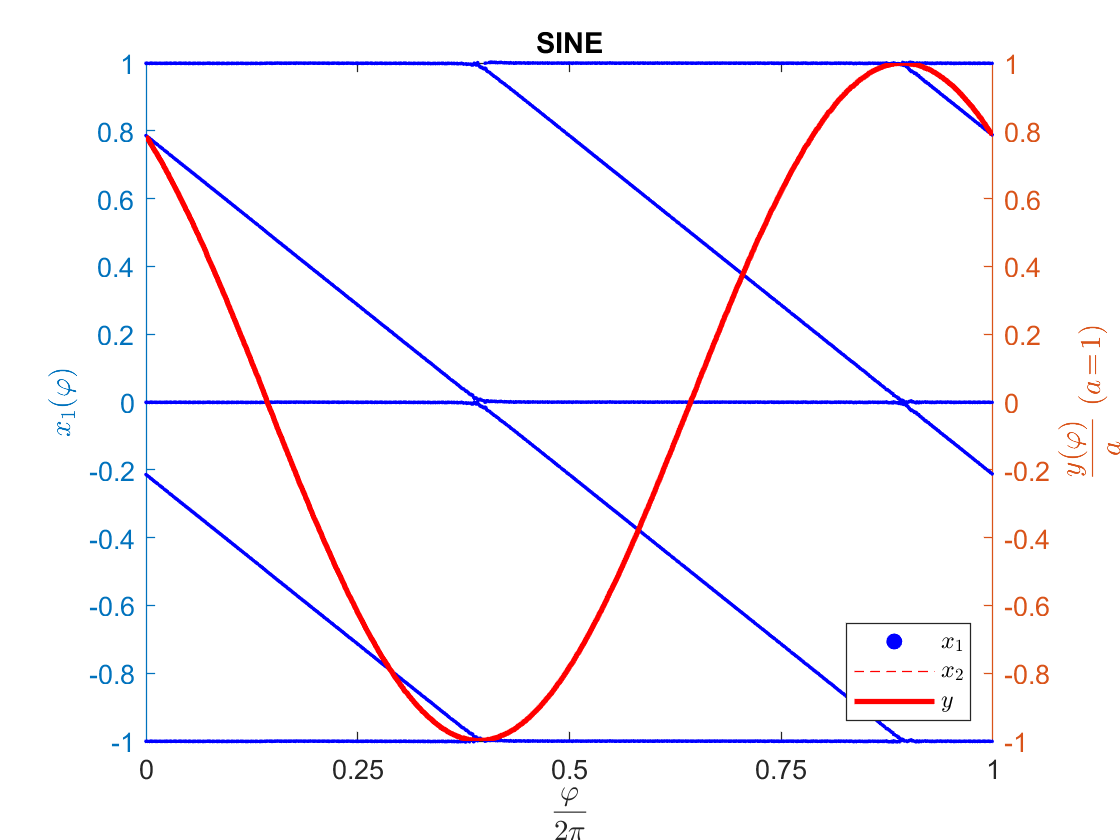

Writing ../waves/wavetable/sampled/SINE.wav ...


SAW1


vVZtools.loadRecording(rid="recordings/phaseDistortionModulationAnalysis/SAW1")
- Read wave file "../waves/recordings/phaseDistortionModulationAnalysis/SAW1.wav"
  - OK, 103260 samples
- Read annotation file "../labels/recordings/phaseDistortionModulationAnalysis/SAW1.par"
  - Read properties
    - OK, 0 properties
  - Read pitch marks
    - OK, 79 pitch marks


    wave: [1024×1 double]
      k0: 17261
       K: 1024



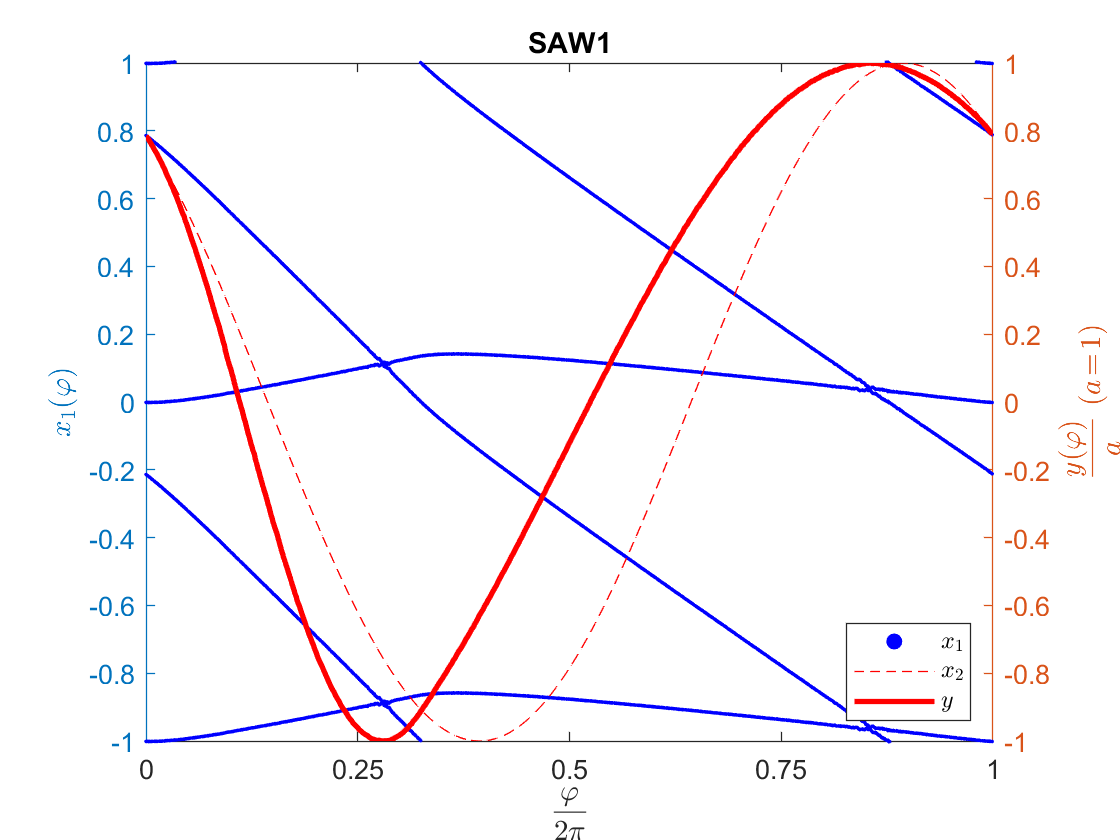

Writing ../waves/wavetable/sampled/SAW1.wav ...


SAW2


vVZtools.loadRecording(rid="recordings/phaseDistortionModulationAnalysis/SAW2")
- Read wave file "../waves/recordings/phaseDistortionModulationAnalysis/SAW2.wav"
  - OK, 109260 samples
- Read annotation file "../labels/recordings/phaseDistortionModulationAnalysis/SAW2.par"
  - Read properties
    - OK, 0 properties
  - Read pitch marks
    - OK, 84 pitch marks


    wave: [1024×1 double]
      k0: 17542
       K: 1024



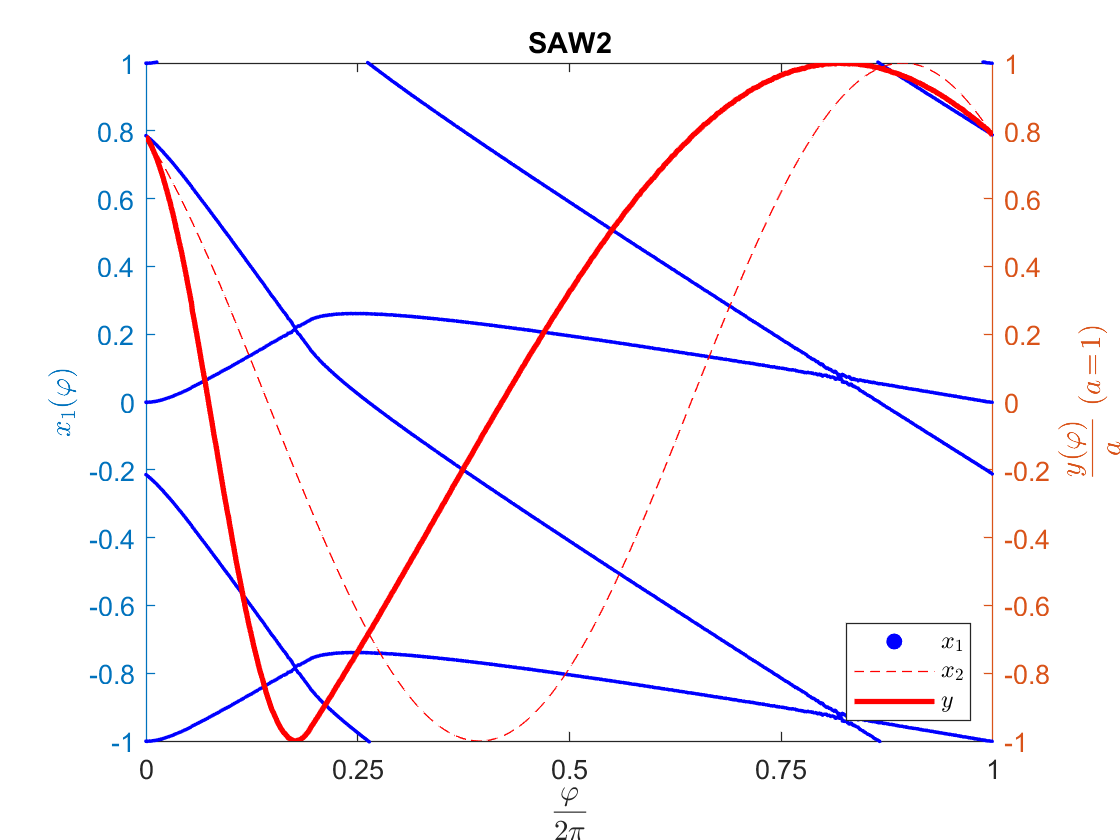

Writing ../waves/wavetable/sampled/SAW2.wav ...


SAW3


vVZtools.loadRecording(rid="recordings/phaseDistortionModulationAnalysis/SAW3")
- Read wave file "../waves/recordings/phaseDistortionModulationAnalysis/SAW3.wav"
  - OK, 94260 samples
- Read annotation file "../labels/recordings/phaseDistortionModulationAnalysis/SAW3.par"
  - Read properties
    - OK, 0 properties
  - Read pitch marks
    - OK, 73 pitch marks


    wave: [1024×1 double]
      k0: 18068
       K: 1024



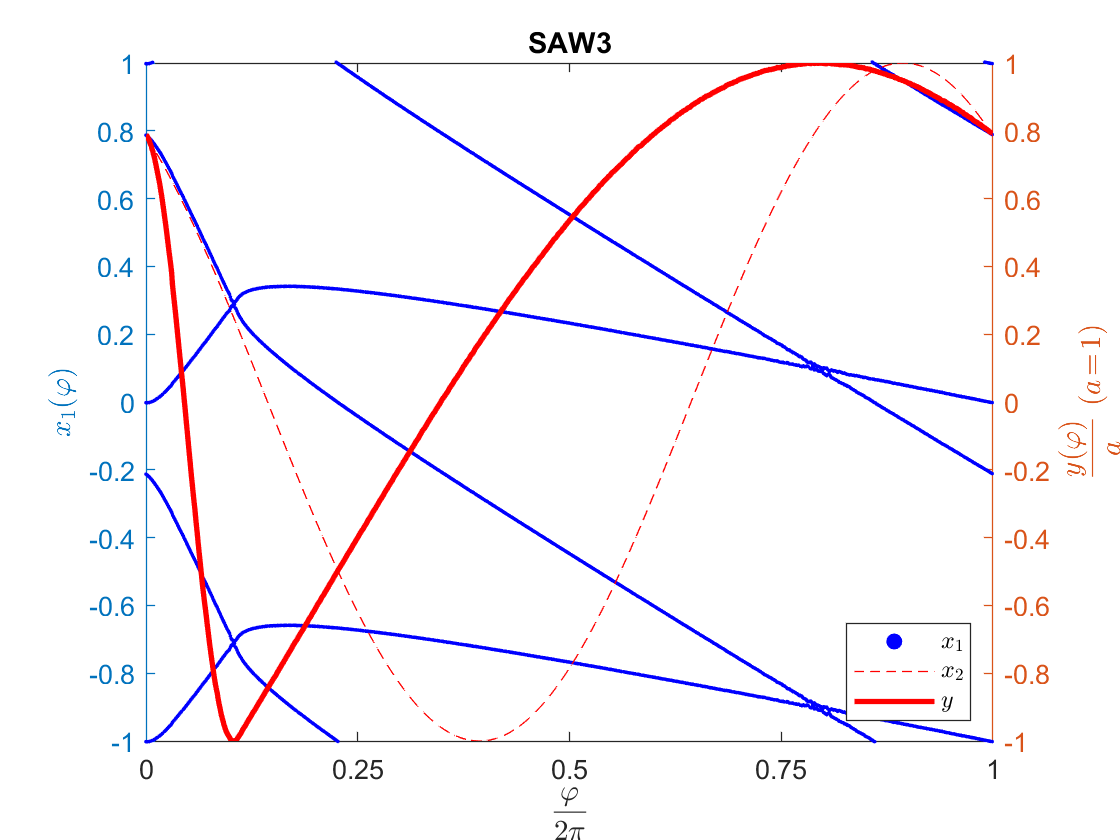

Writing ../waves/wavetable/sampled/SAW3.wav ...


SAW4


vVZtools.loadRecording(rid="recordings/phaseDistortionModulationAnalysis/SAW4")
- Read wave file "../waves/recordings/phaseDistortionModulationAnalysis/SAW4.wav"
  - OK, 107760 samples
- Read annotation file "../labels/recordings/phaseDistortionModulationAnalysis/SAW4.par"
  - Read properties
    - OK, 0 properties
  - Read pitch marks
    - OK, 81 pitch marks


    wave: [1024×1 double]
      k0: 19074
       K: 1024



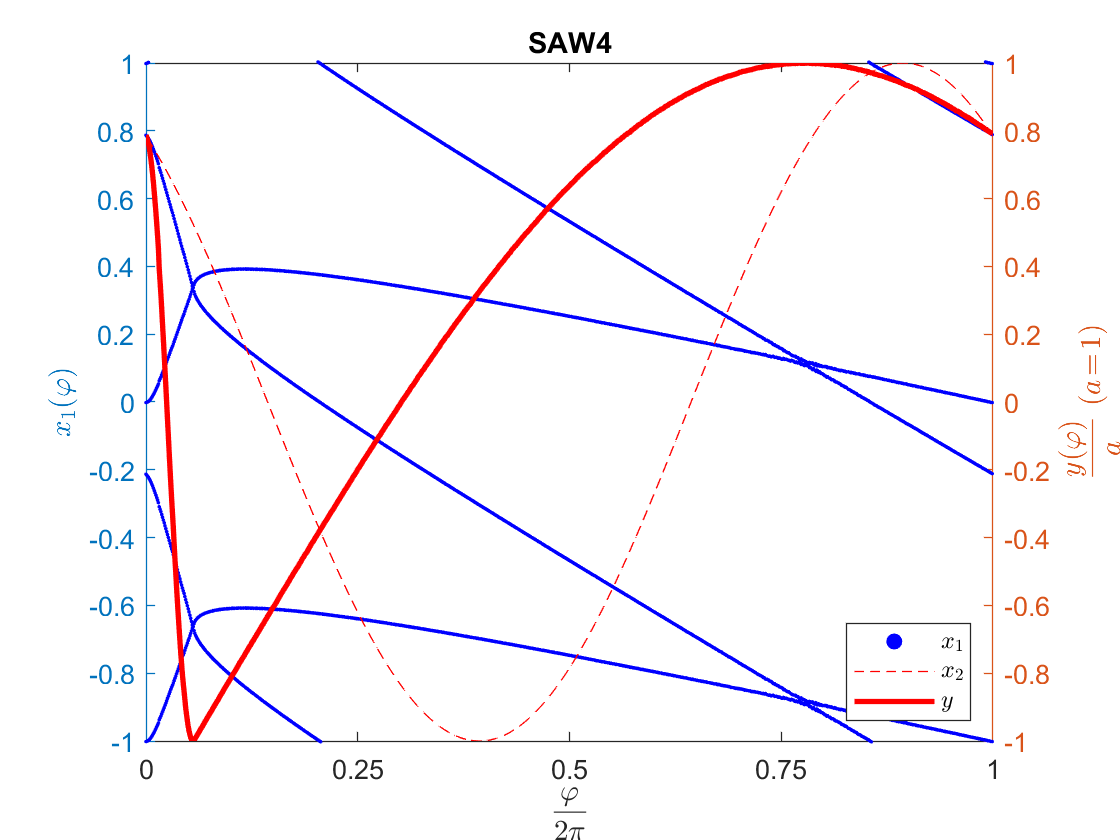

Writing ../waves/wavetable/sampled/SAW4.wav ...


SAW5


vVZtools.loadRecording(rid="recordings/phaseDistortionModulationAnalysis/SAW5")
- Read wave file "../waves/recordings/phaseDistortionModulationAnalysis/SAW5.wav"
  - OK, 105400 samples
- Read annotation file "../labels/recordings/phaseDistortionModulationAnalysis/SAW5.par"
  - Read properties
    - OK, 0 properties
  - Read pitch marks
    - OK, 82 pitch marks


    wave: [1024×1 double]
      k0: 17285
       K: 1024



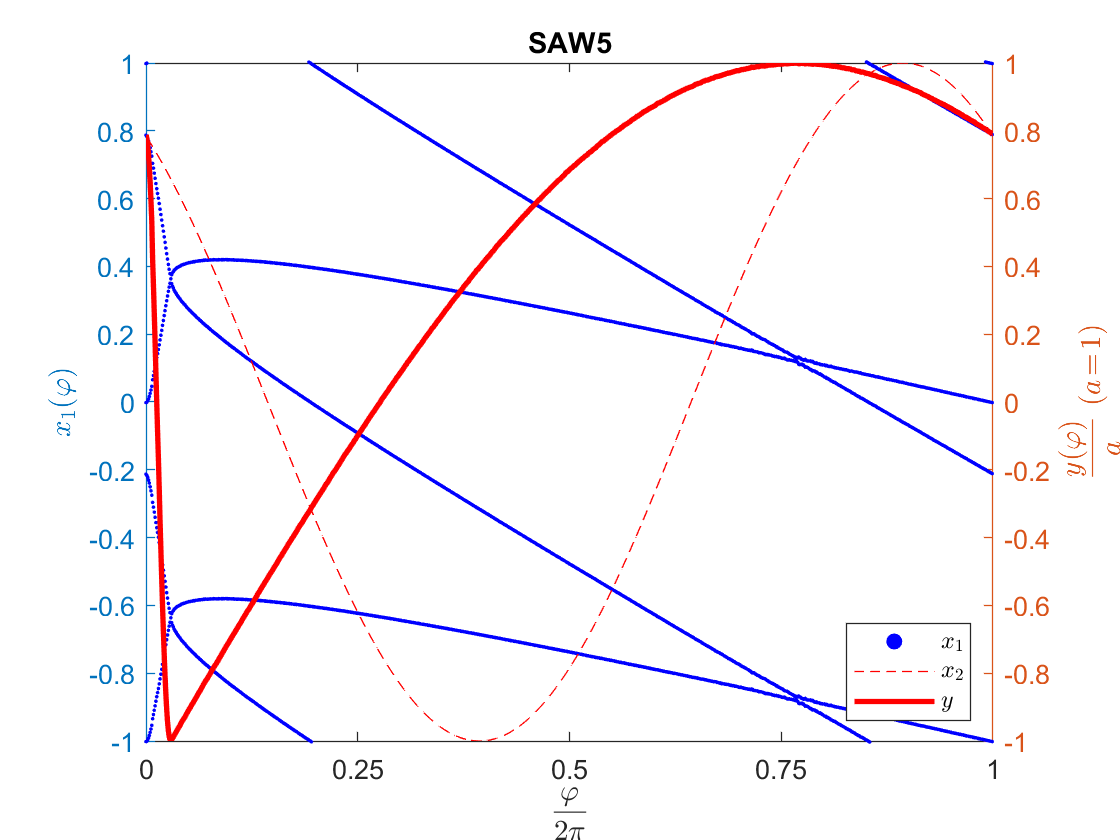

Writing ../waves/wavetable/sampled/SAW5.wav ...


f_S    = 48000;
K0     = 1024;
pfxIn  = 'recordings/phaseDistortionModulationAnalysis/';
pfxOut = '../waves/wavetable/sampled/';
rlst   = { 'SINE'; 'SAW1'; 'SAW2'; 'SAW3'; 'SAW4'; 'SAW5' };
k0y    = [    146;     96;     56;     32;     16;      8 ]; % Phase shift of y in samples
k0x2   = [    110;    110;    110;    110;    110;    110 ]; % Phase shift of x2 in samples

recs = struct([]);
for i=1:length(rlst)
  fprintf('%s\n',rlst{i});
  [rec.wave,pm,~] = vVZtools.loadRecording([pfxIn rlst{i}]);
  [rec.wave,rec.k0] = vVZtools.cutNiceCycle(rec.wave,pm,[7 length(pm)-3],K0);
  rec.K    = length(rec.wave);
  wmin     = min(rec.wave);
  wmax     = max(rec.wave);
  rec.wave = 2*(rec.wave-wmin)/(wmax-wmin)-1; % Normalize to y in [-1,1]
  rec.wave = circshift(rec.wave,k0y(i));
  disp(rec);
  
  k  = 0:rec.K-1;
  y  = rec.wave;
  x2 = sin(2*pi.*(k+k0x2(i))/rec.K+pi/2); % The carrier signal to be modulated
  x1 = vVZtools.pmInvert(y,x2);           % The phase-modulating signal
  
  vVZtools.plotPmInvert(y,x1,rlst{i},[-1 1],1); hold on;
  plot(x2,'--r');
  legend('$$x_1$$','$$x_2$$','$$y$$','interpreter','latex','Location','southeast');

  % Write recorded wavetable signal
  fnOut = [pfxOut rlst{i} '.wav'];
  fprintf('Writing %s ...\n',fnOut);
  audiowrite(fnOut,rec.wave,f_S);

  if i==1; recs=rec; else; recs(i)=rec; end
end

We see in the Figures that the expectations regarding the modulating signal $x_1$ roughly hold.

### 2.3   Modeling the Wavetable Samples

fprintf('2.3 Modeling the Wavetable Samples');

2.3 Modeling the Wavetable Samples

I try to model the `SAWn` oscillator waveforms by piecwise linear PDM of a sine wave.

#### 2.3.1   Unmodified PDM of a Sine Wave

fprintf('2.3.1 Unmodified PDM of a Sine Wave');

2.3.1 Unmodified PDM of a Sine Wave

First I test an unmodified PDM as described above.

SINE


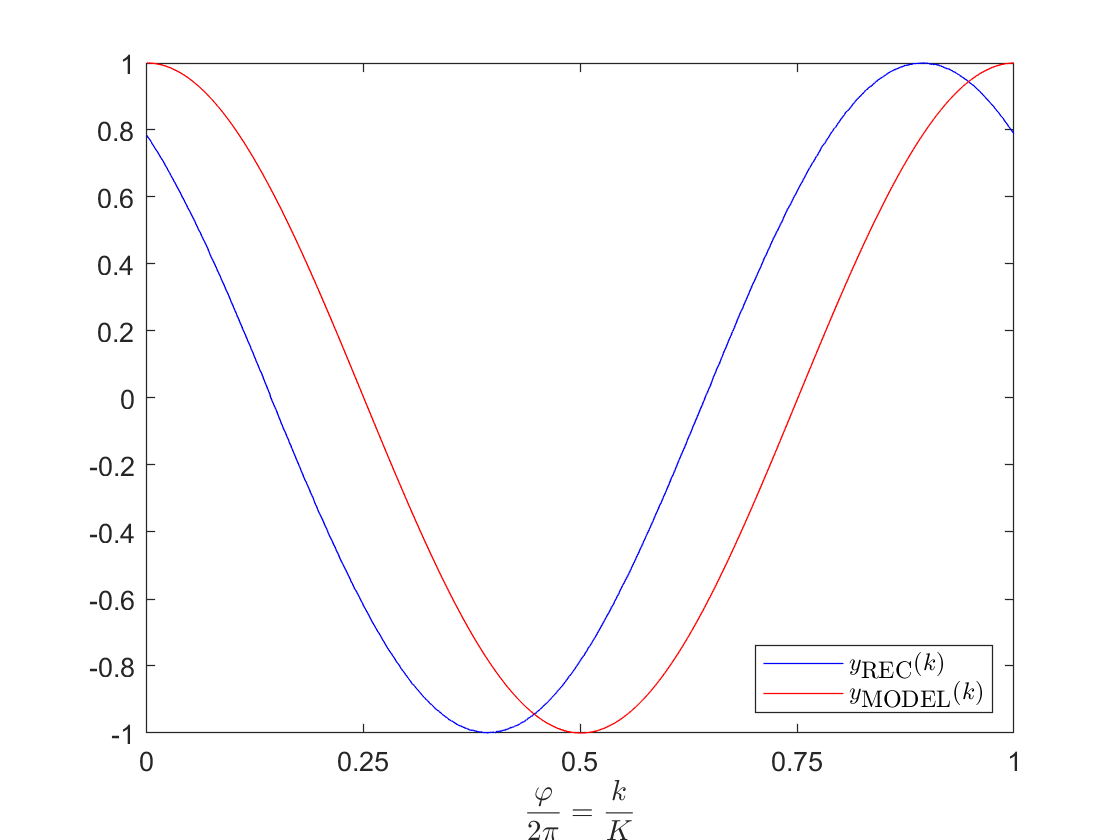

Writing ../waves/wavetable/generated-purePDM/SINE.wav ...


SAW1


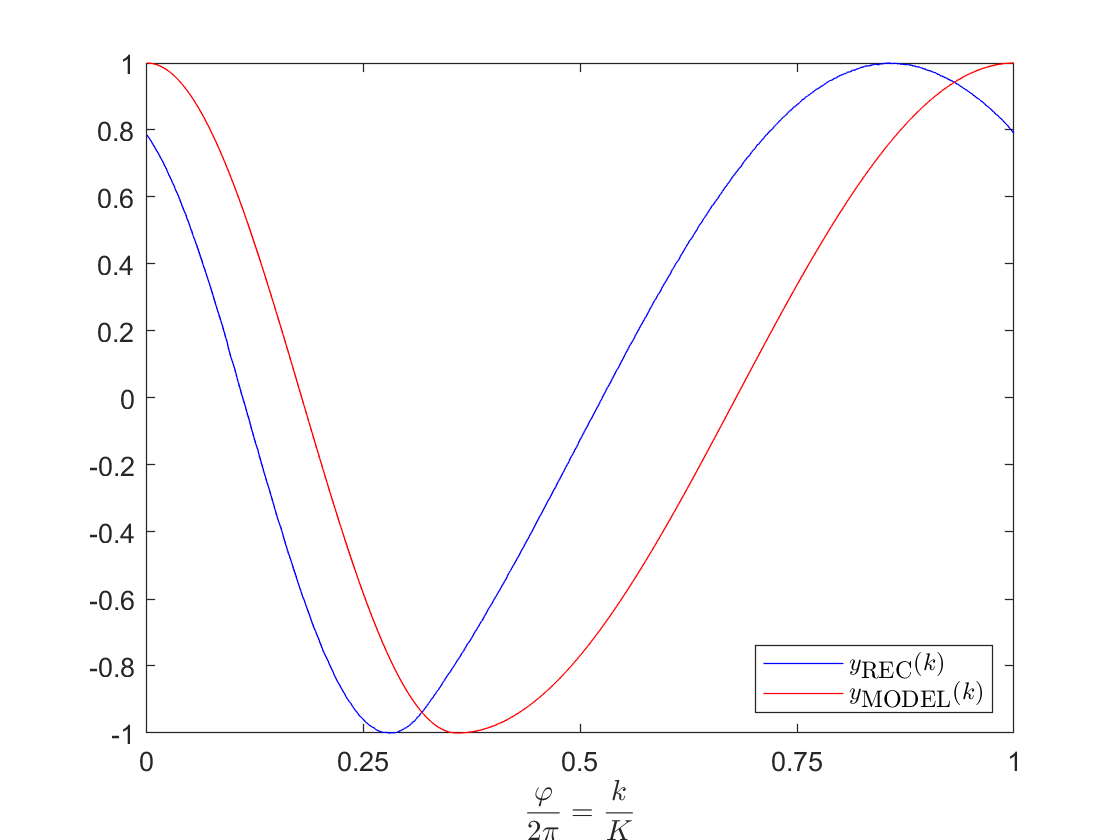

Writing ../waves/wavetable/generated-purePDM/SAW1.wav ...


SAW2


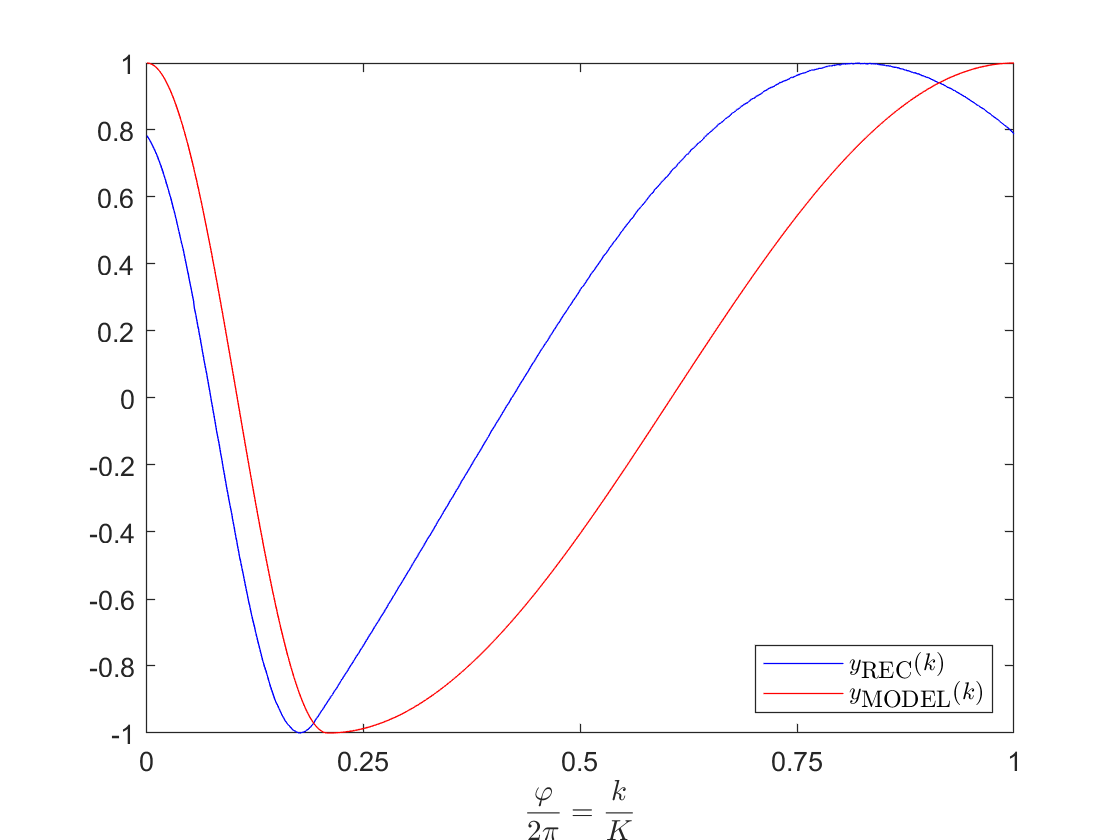

Writing ../waves/wavetable/generated-purePDM/SAW2.wav ...


SAW3


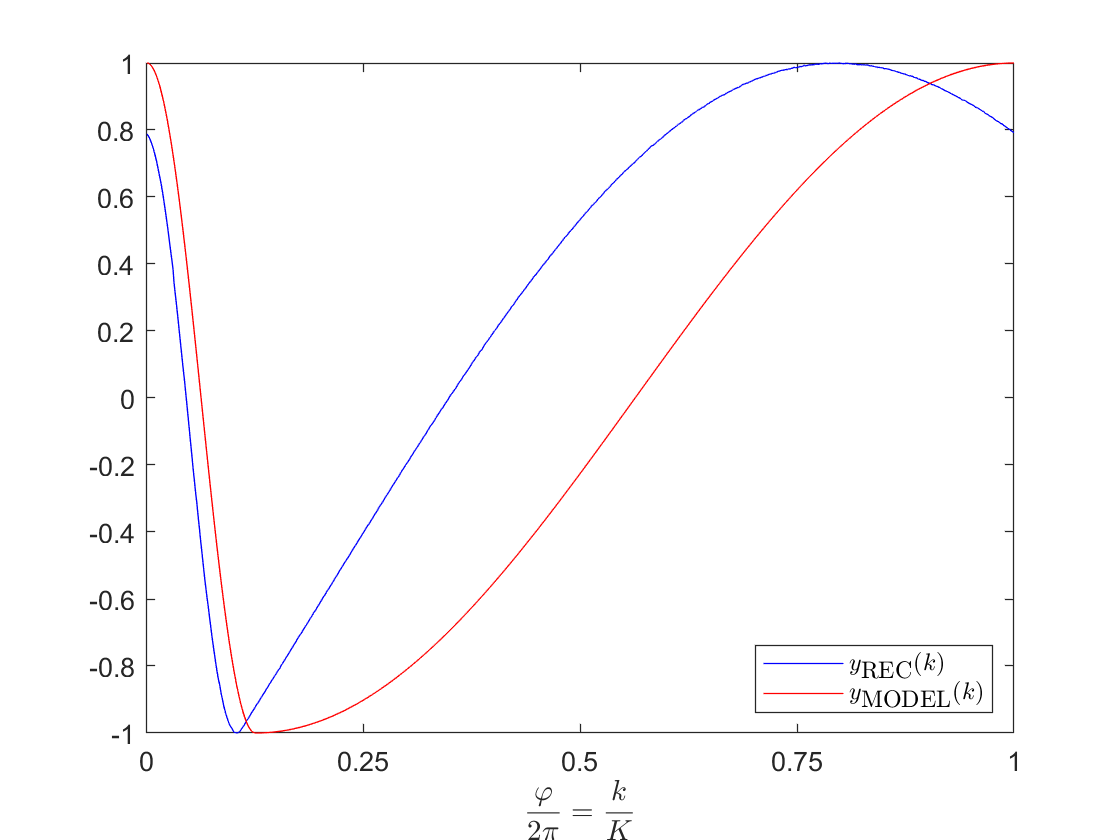

Writing ../waves/wavetable/generated-purePDM/SAW3.wav ...


SAW4


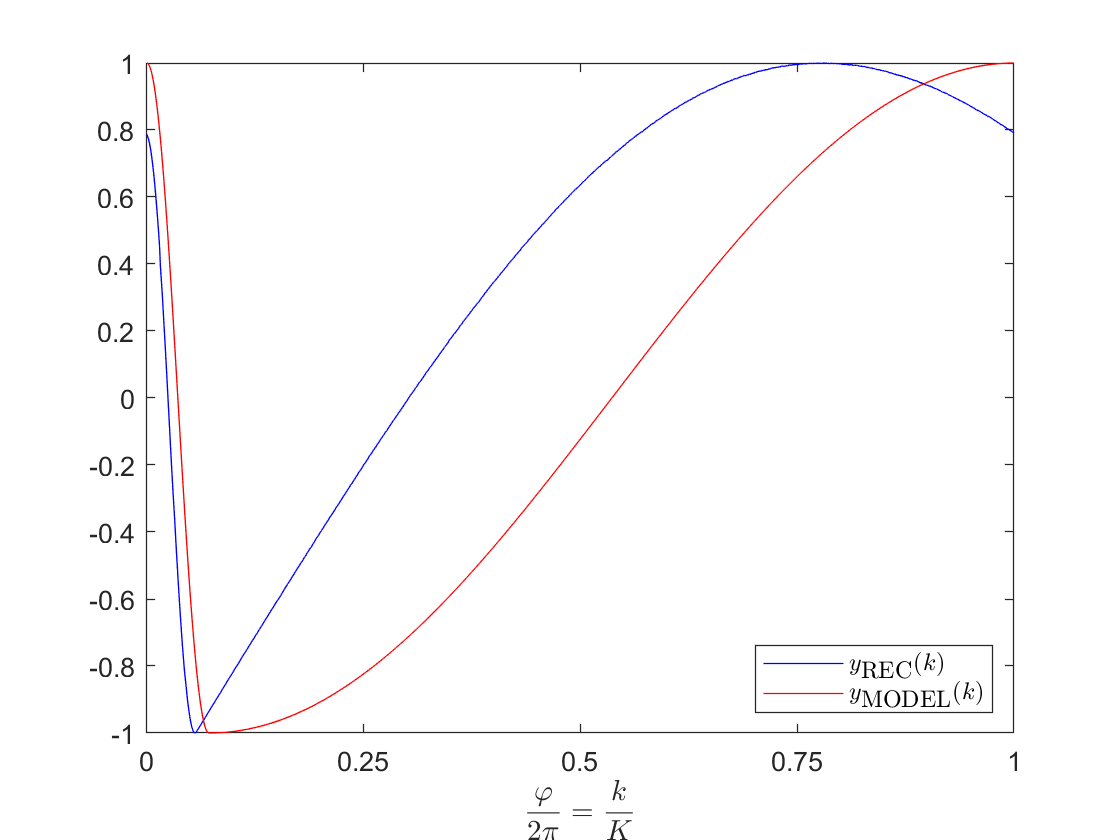

Writing ../waves/wavetable/generated-purePDM/SAW4.wav ...


SAW5


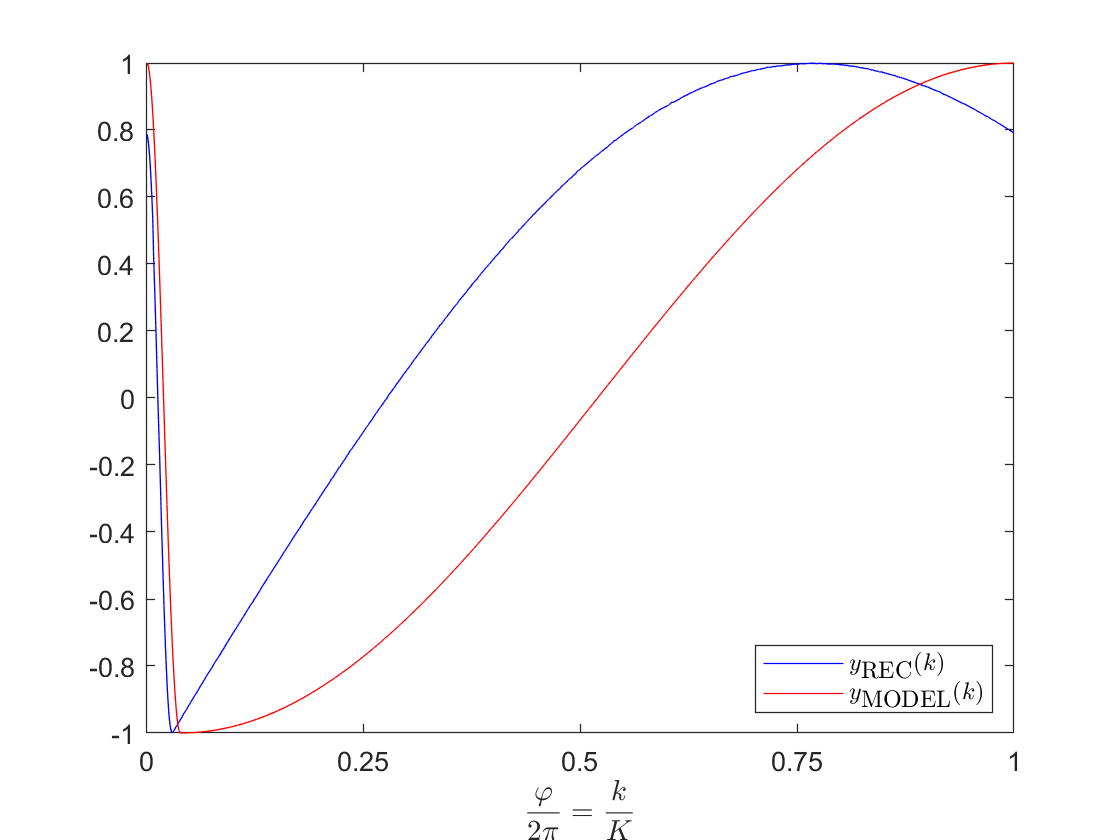

Writing ../waves/wavetable/generated-purePDM/SAW5.wav ...


pfxOut = '../waves/wavetable/generated-purePDM/';

%     SINE SAW1 SAW2 SAW3 SAW4 SAW5
a = [    1; 1.4; 2.4;   4;   7;  13 ];
for i=1:length(rlst)
  fprintf('%s\n',rlst{i});
  K = rec.K;
  k = 0:K-1;
  y = sin(vVZtools.PDMcc(2*pi*k/K,a(i))+pi/2);
  
  figure;
  plot(recs(i).wave,'-b'); hold on;
  plot(y           ,'-r');
  xlim([0 K]);
  xlabel('$$\frac{\varphi}{2\pi}=\frac{k}{K}$$','Interpreter','latex');
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  legend('$$y_{\mbox{REC}}(k)$$','$$y_{\mbox{MODEL}}(k)$$','interpreter','latex','Location','southeast');
  
  % Write modeled wavetable signal
  fnOut = [pfxOut rlst{i} '.wav'];
  fprintf('Writing %s ...\n',fnOut);
  audiowrite(fnOut,y,f_S);
end

We see a clear phase shift between the recorded and modeled waveforms.

#### 2.3.2   PDM of a Phase-Shifted Sine Wave

fprintf('2.3.2 PDM of a Phase-Shifted Sine Wave');

2.3.2 PDM of a Phase-Shifted Sine Wave

Next, I compensate the phase shift observed above by phase-shifting the modulated sines by $k_{0,x2}$ samples.

SINE


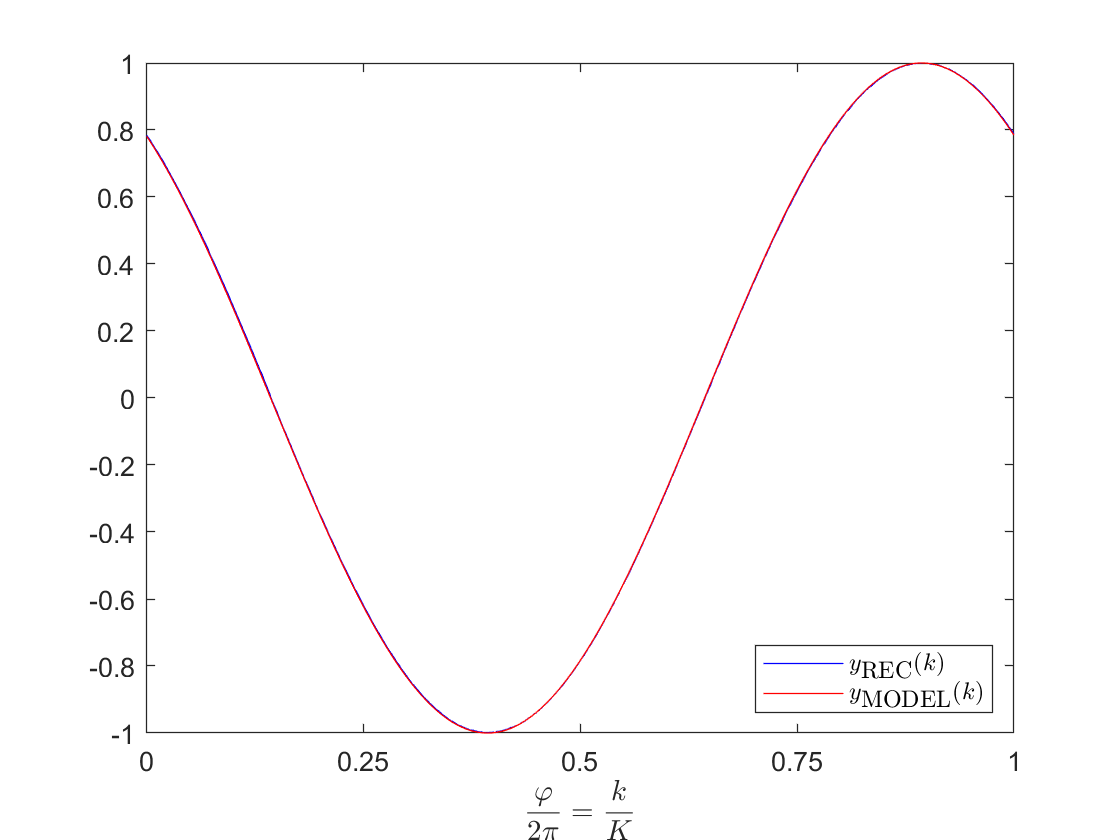

SAW1


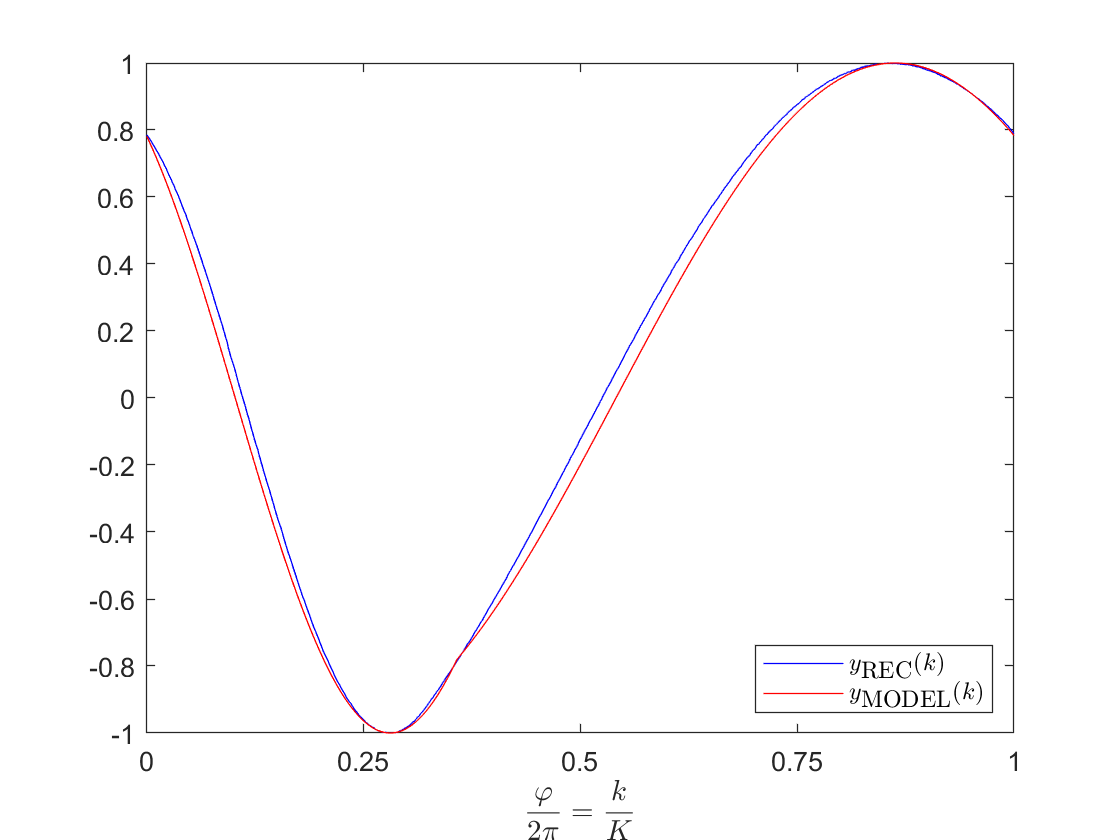

SAW2


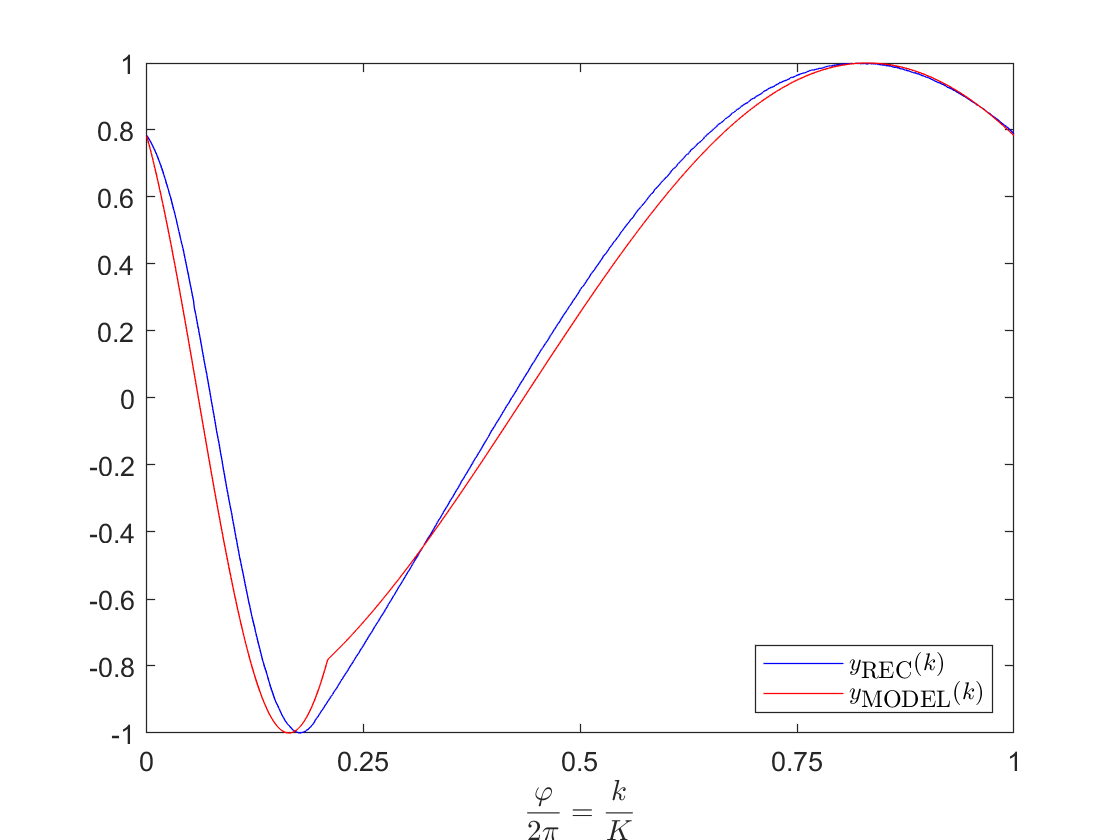

SAW3


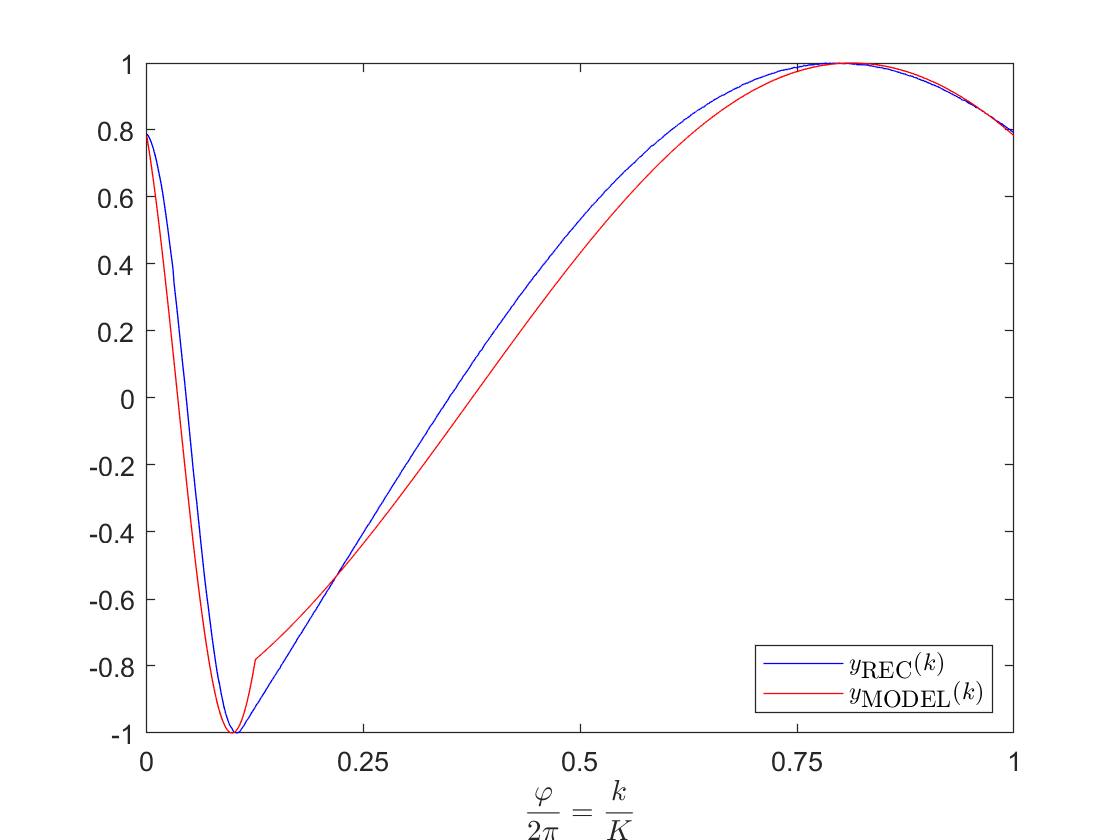

SAW4


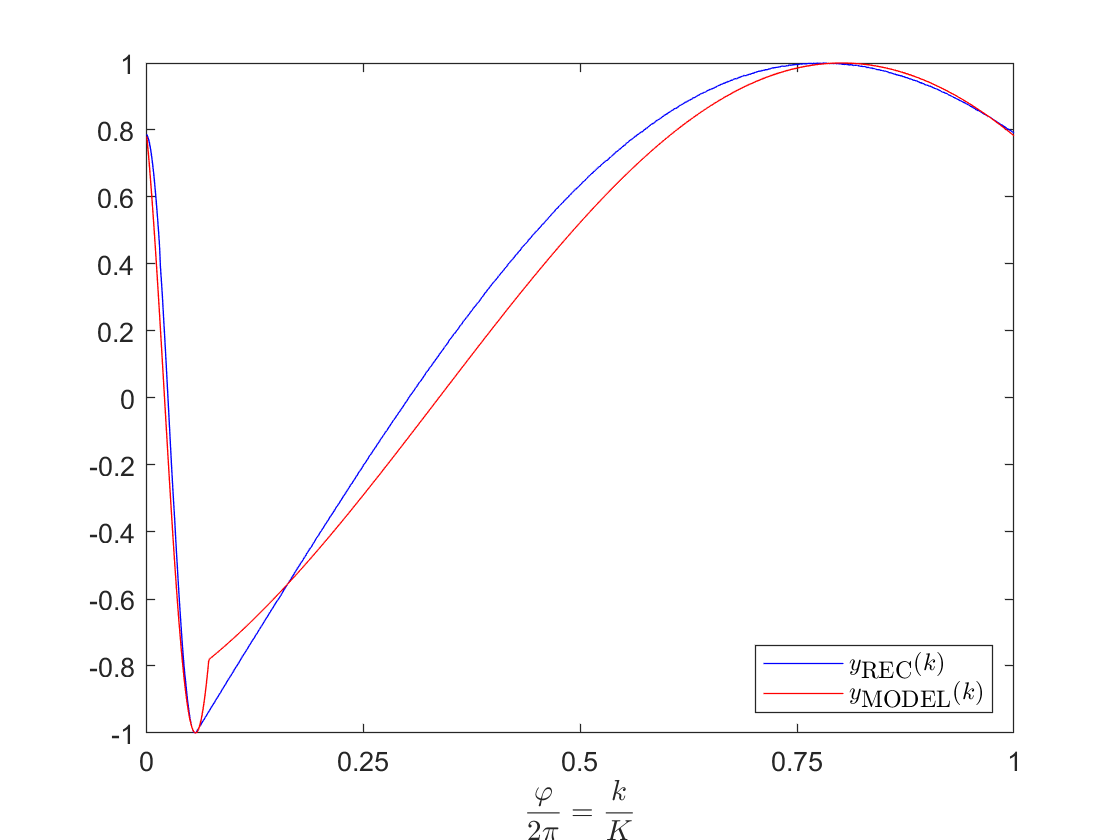

SAW5


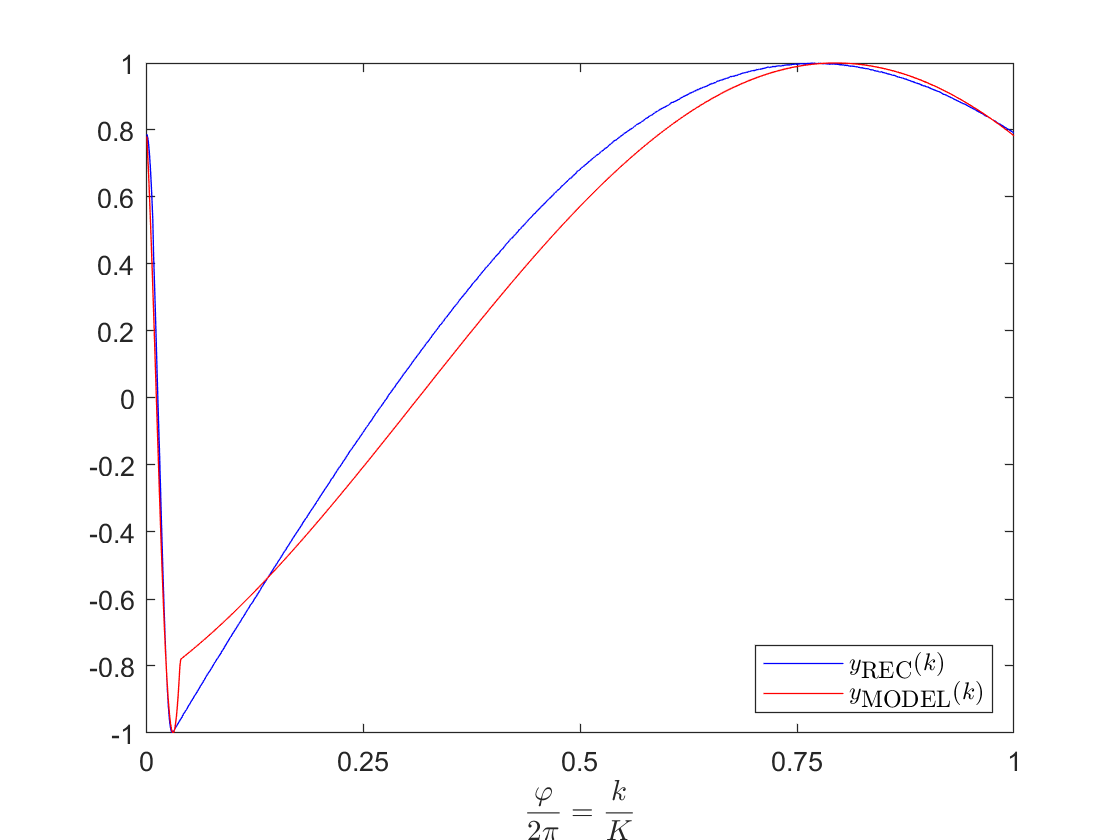

%     SINE SAW1 SAW2 SAW3 SAW4 SAW5
a = [    1; 1.4; 2.4;   4;   7;  13 ];
for i=1:length(rlst)
  fprintf('%s\n',rlst{i});
  K = rec.K;
  k = 0:K-1;
  y = sin(vVZtools.PDMcc(2*pi*k/K,a(i))+pi/2+2*pi*k0x2(i)/K);
  
  figure;
  plot(recs(i).wave,'-b'); hold on;
  plot(y           ,'-r');
  xlim([0 K]);
  xlabel('$$\frac{\varphi}{2\pi}=\frac{k}{K}$$','Interpreter','latex');
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  legend('$$y_{\mbox{REC}}(k)$$','$$y_{\mbox{MODEL}}(k)$$','interpreter','latex','Location','southeast');
end

We see that the model waveforms corresond quire well with the reocorded ones. However, there is a significant difference near the minimum which increases with modulation depth (slope parameter *a*).

#### 2.3.3   Optimized PDM

fprintf('2.3.3 Optimized PDM');

2.3.3 Optimized PDM

Finally, I try correct the bend near the minimum by adjusting the PDM characteristic curve.

To this end I introduce a phase shift parameter $\varphi_0$ into the characteristic curve. As the transition from speed-up to slow-down---i.e., the "bend" of the chcracteristic---must occur at the minimum of the input inverted cosine, I modify the bend point of the characteristic as follows:

    $f_1(\varphi)=a\varphi$,        $0\leq\varphi\leq\varphi_B$,    running through the points $(0,0)$ and $(\varphi_B,\pi-\varphi_0)$ and

    $f_2(\varphi) = b\varphi+c$,  $\varphi_B\leq \varphi< 2\pi$,  running through the points $(\varphi_B,\pi-\varphi_0)$ and $(2\pi,2\pi)$.

Taking $a$ and $\varphi_0$ as the free parameters, I obtain an adjusted characteristic curve:

syms a b c phi phiB phi0 real;
assume(a>=0 & -pi<phi0 & phi0<pi);
eqns = [               ...
  a*phiB   == pi-phi0, ...
  b*phiB+c == pi-phi0, ...
  b*2*pi+c == 2*pi     ...
];
S = solve(eqns,[phiB,b,c]);
phiB  = simplify(S.phiB);  fprintf('  phiB ='                 ); disp(phiB);

  phiB =

$$-\frac{\varphi_{0}-\pi }{a}$$

b     = simplify(S.b);     fprintf('  b ='                    ); disp(b);

  b =

$$\frac{a\,\left(\varphi_{0}+\pi \right)}{\varphi_{0}-\pi +2\,\pi \,a}$$

c     = simplify(S.c);     fprintf('  c ='                    ); disp(c);

  c =

$$-\frac{2\,\pi \,\left(\varphi_{0}-\pi \right)\,\left(a-1\right)}{\varphi_{0}-\pi +2\,\pi \,a}$$

phiVZ = simplify(b*phi+c); fprintf('  phiVZ(phi) = b*phi+c = '); disp(phiVZ);

  phiVZ(phi) = b*phi+c = 

$$\frac{a\,\varphi \,\left(\varphi_{0}+\pi \right)}{\varphi_{0}-\pi +2\,\pi \,a}-\frac{2\,\pi \,\left(\varphi_{0}-\pi \right)\,\left(a-1\right)}{\varphi_{0}-\pi +2\,\pi \,a}$$

The formula of the characteristic is

    
$$\varphi_{\text{VZ}}(\varphi)
= \begin{cases}
    a\varphi 
    & \text{for } 0\leq\varphi<\frac{\pi-\phi_0}{a}
    \\
    \frac{a(\varphi_0+\pi)\,\varphi-2\pi(\varphi_0-\pi)(a-1)}{\varphi_0-\pi+2\pi a}
    & \text{for } \frac{\pi-\phi_0}{a}\leq\varphi<2\pi
   \end{cases}$$


and the phase-modulated waveforms can be expressed as

    
$$x_\text{VZ}(t) = \sin\left(\varphi_{\text{VZ}}(\varphi)+\frac{\pi}{2}+\varphi_0\right).$$


SINE


Writing ../waves/wavetable/generated-optimized4VZ/SINE.wav ...


SAW1


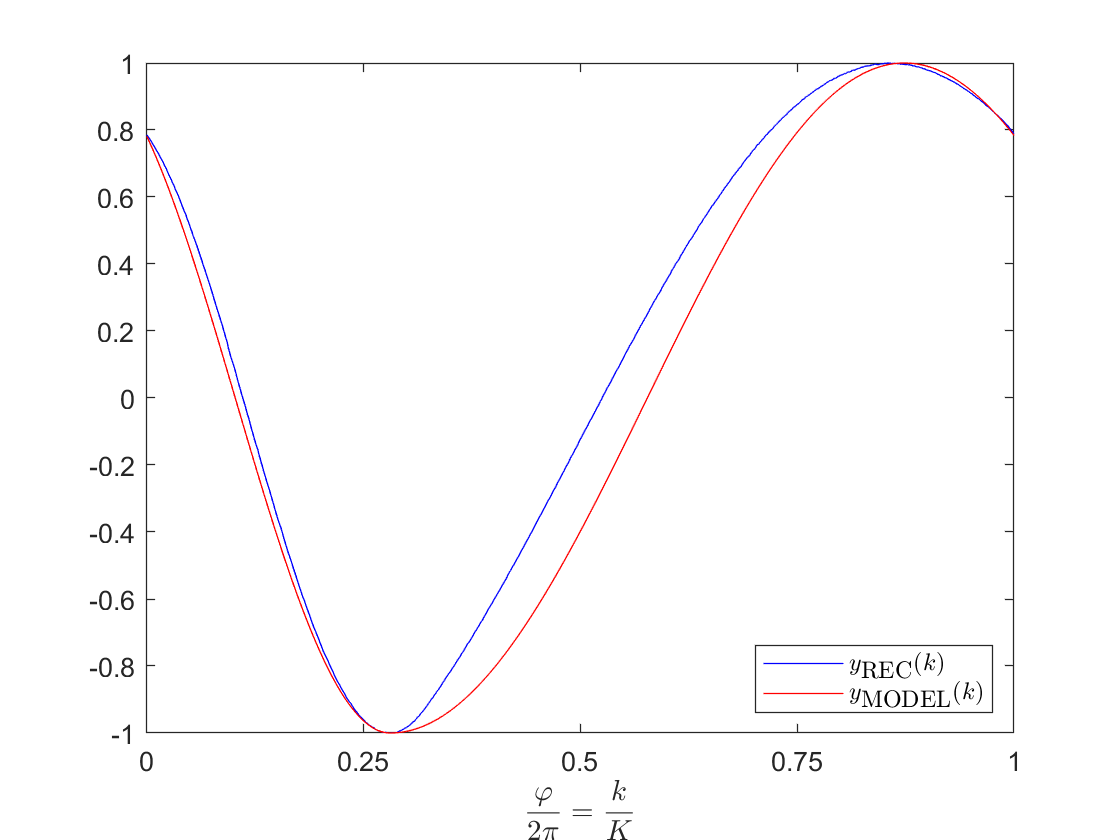

Writing ../waves/wavetable/generated-optimized4VZ/SAW1.wav ...


SAW2


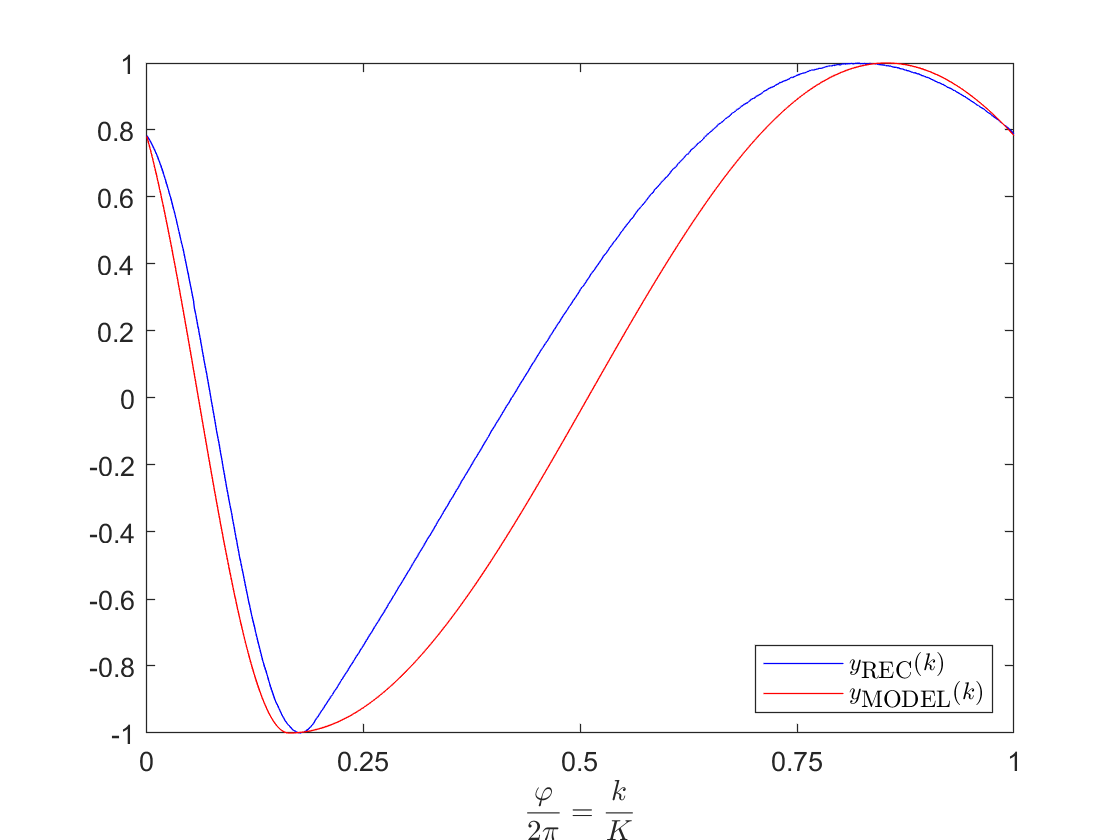

Writing ../waves/wavetable/generated-optimized4VZ/SAW2.wav ...


SAW3


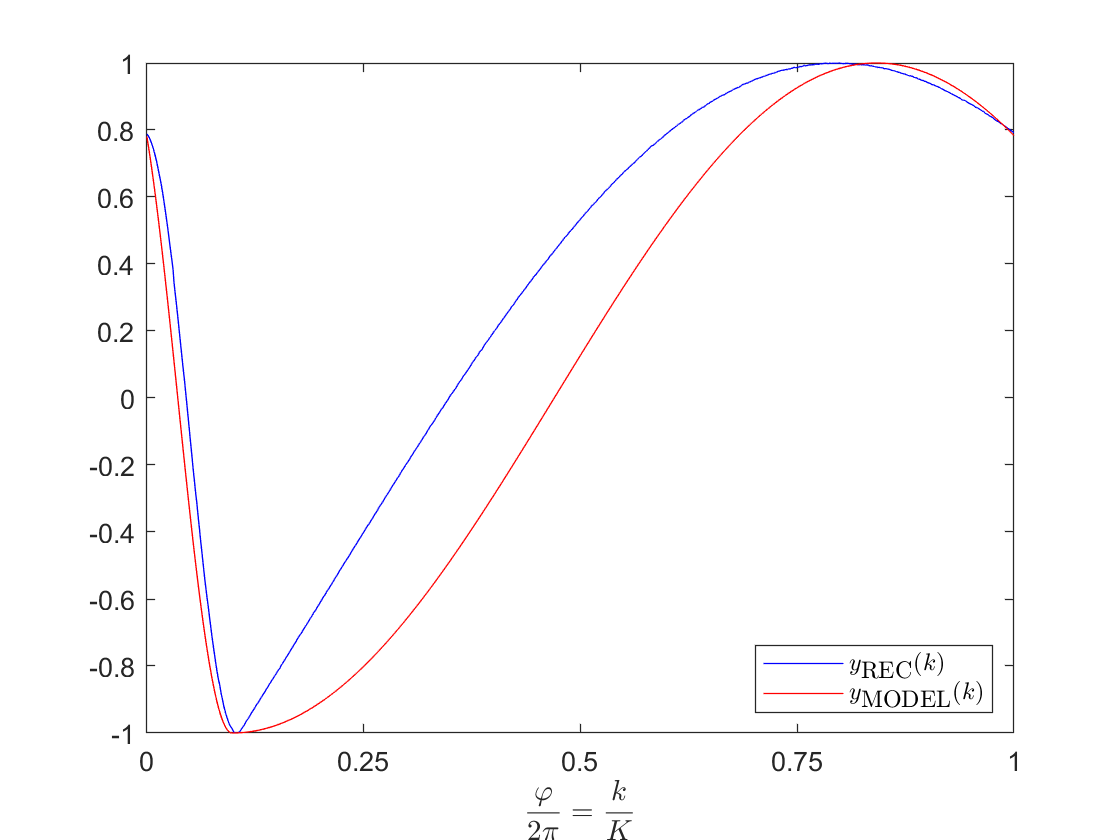

Writing ../waves/wavetable/generated-optimized4VZ/SAW3.wav ...


SAW4


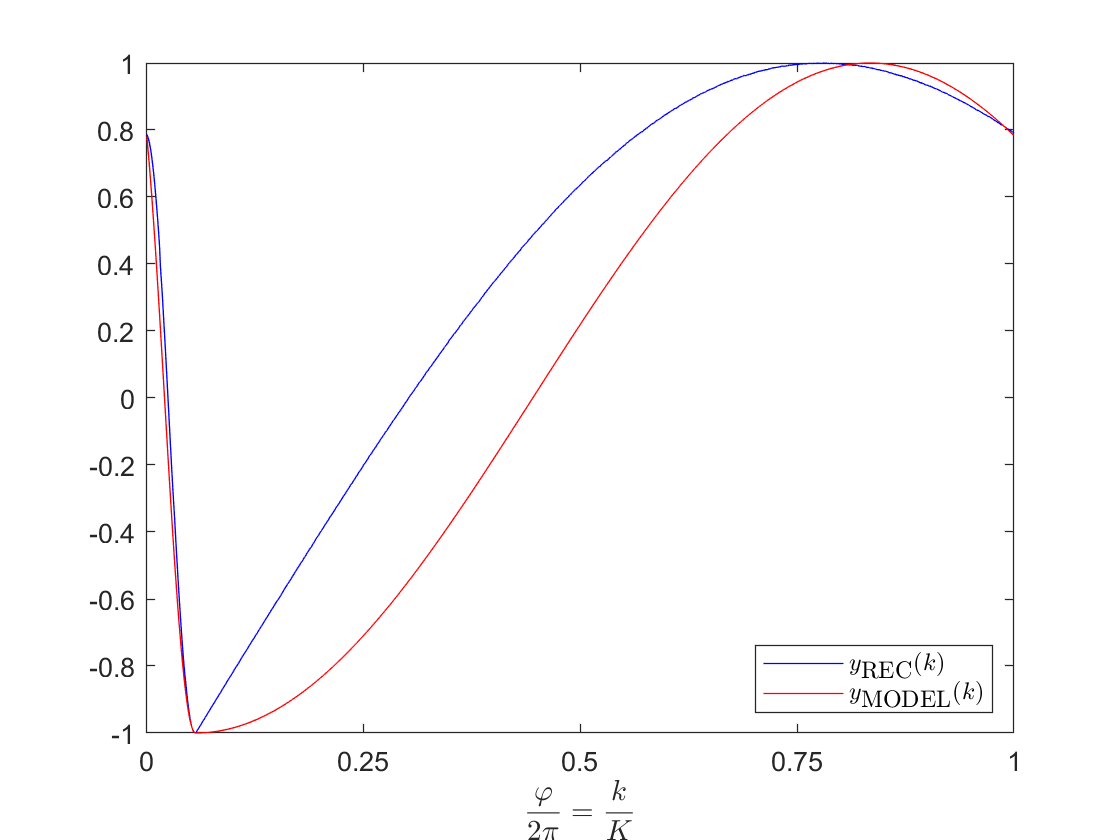

Writing ../waves/wavetable/generated-optimized4VZ/SAW4.wav ...


SAW5


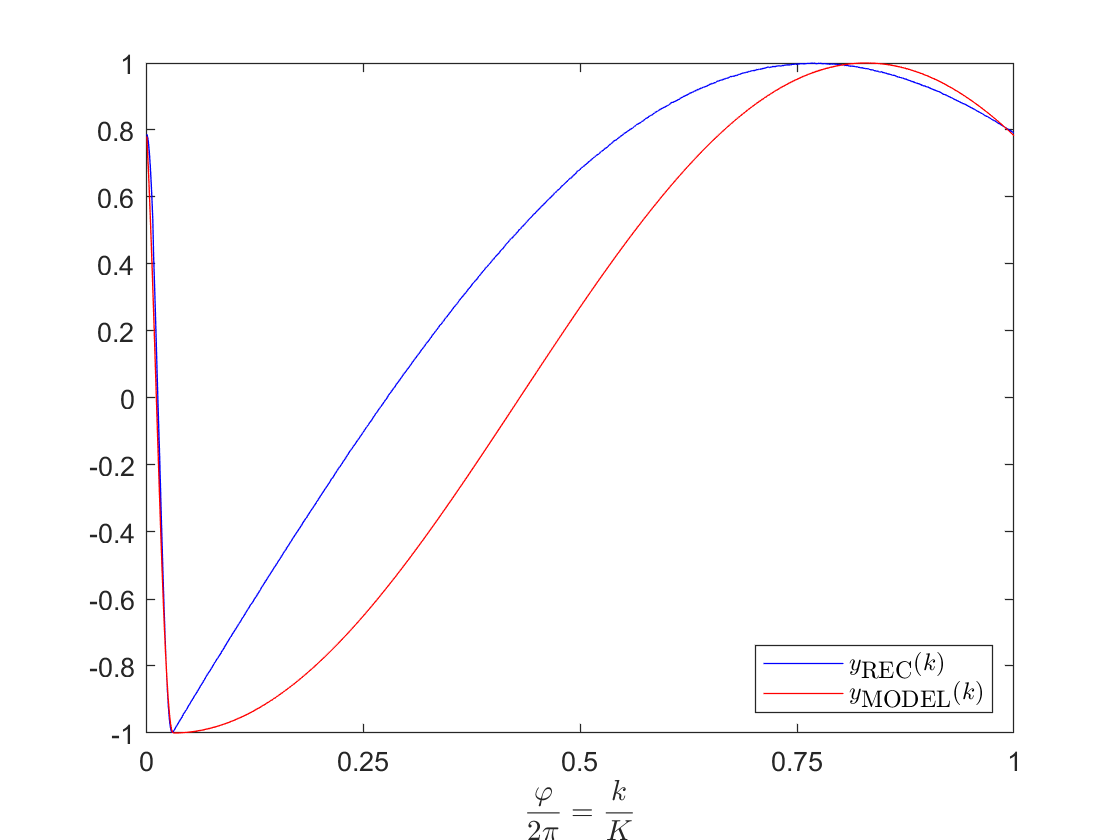

Writing ../waves/wavetable/generated-optimized4VZ/SAW5.wav ...


pfxOut = '../waves/wavetable/generated-optimized4VZ/';

%     SINE SAW1 SAW2 SAW3 SAW4 SAW5
a = [    1; 1.4; 2.4;   4;   7;  13 ];
for i=1:length(rlst)
  fprintf('%s\n',rlst{i});
  K = rec.K;
  k = 0:K-1;
  y = sin(vVZtools.PDMccVZ(2*pi*k/K,a(i),2*pi*k0x2(i)/K)+pi/2+2*pi*k0x2(i)/K);
  
  figure;
  plot(recs(i).wave,'-b'); hold on;
  plot(y           ,'-r');
  xlim([0 K]);
  xlabel('$$\frac{\varphi}{2\pi}=\frac{k}{K}$$','Interpreter','latex');
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  legend('$$y_{\mbox{REC}}(k)$$','$$y_{\mbox{MODEL}}(k)$$','interpreter','latex','Location','southeast');
  
  % Write modeled wavetable signal
  fnOut = [pfxOut rlst{i} '.wav'];
  fprintf('Writing %s ...\n',fnOut);
  audiowrite(fnOut,y,f_S);
end

The adjusment corrects the modeled signal values near the minimum as expected. However, it also slows down the subsequent risigng edge, introduction additional difference between modeled and recorded signal.

## 3   Conclusion

The `SINE` waveform of VZ with a cycle length of $K=1024$ samples can be reproduced by

    $y_{\text{SINE}}(k) = \sin\left(2\pi\frac{k+k_{0,x2}}{K}+\frac{\pi}{2}\right)$   with $k_{0,x2}=110$.

The `SAWn` waveforms cannot be decently explained by a piecewise linear phase distortion model. The best model is 2.3.2. The modulation triagle signal $x_1$ might be low-pass filtered for improvement. However, this does not seem worthwile to me. I am just going to use recorded cycles for the wavetable oscillators of the virtual instrument.